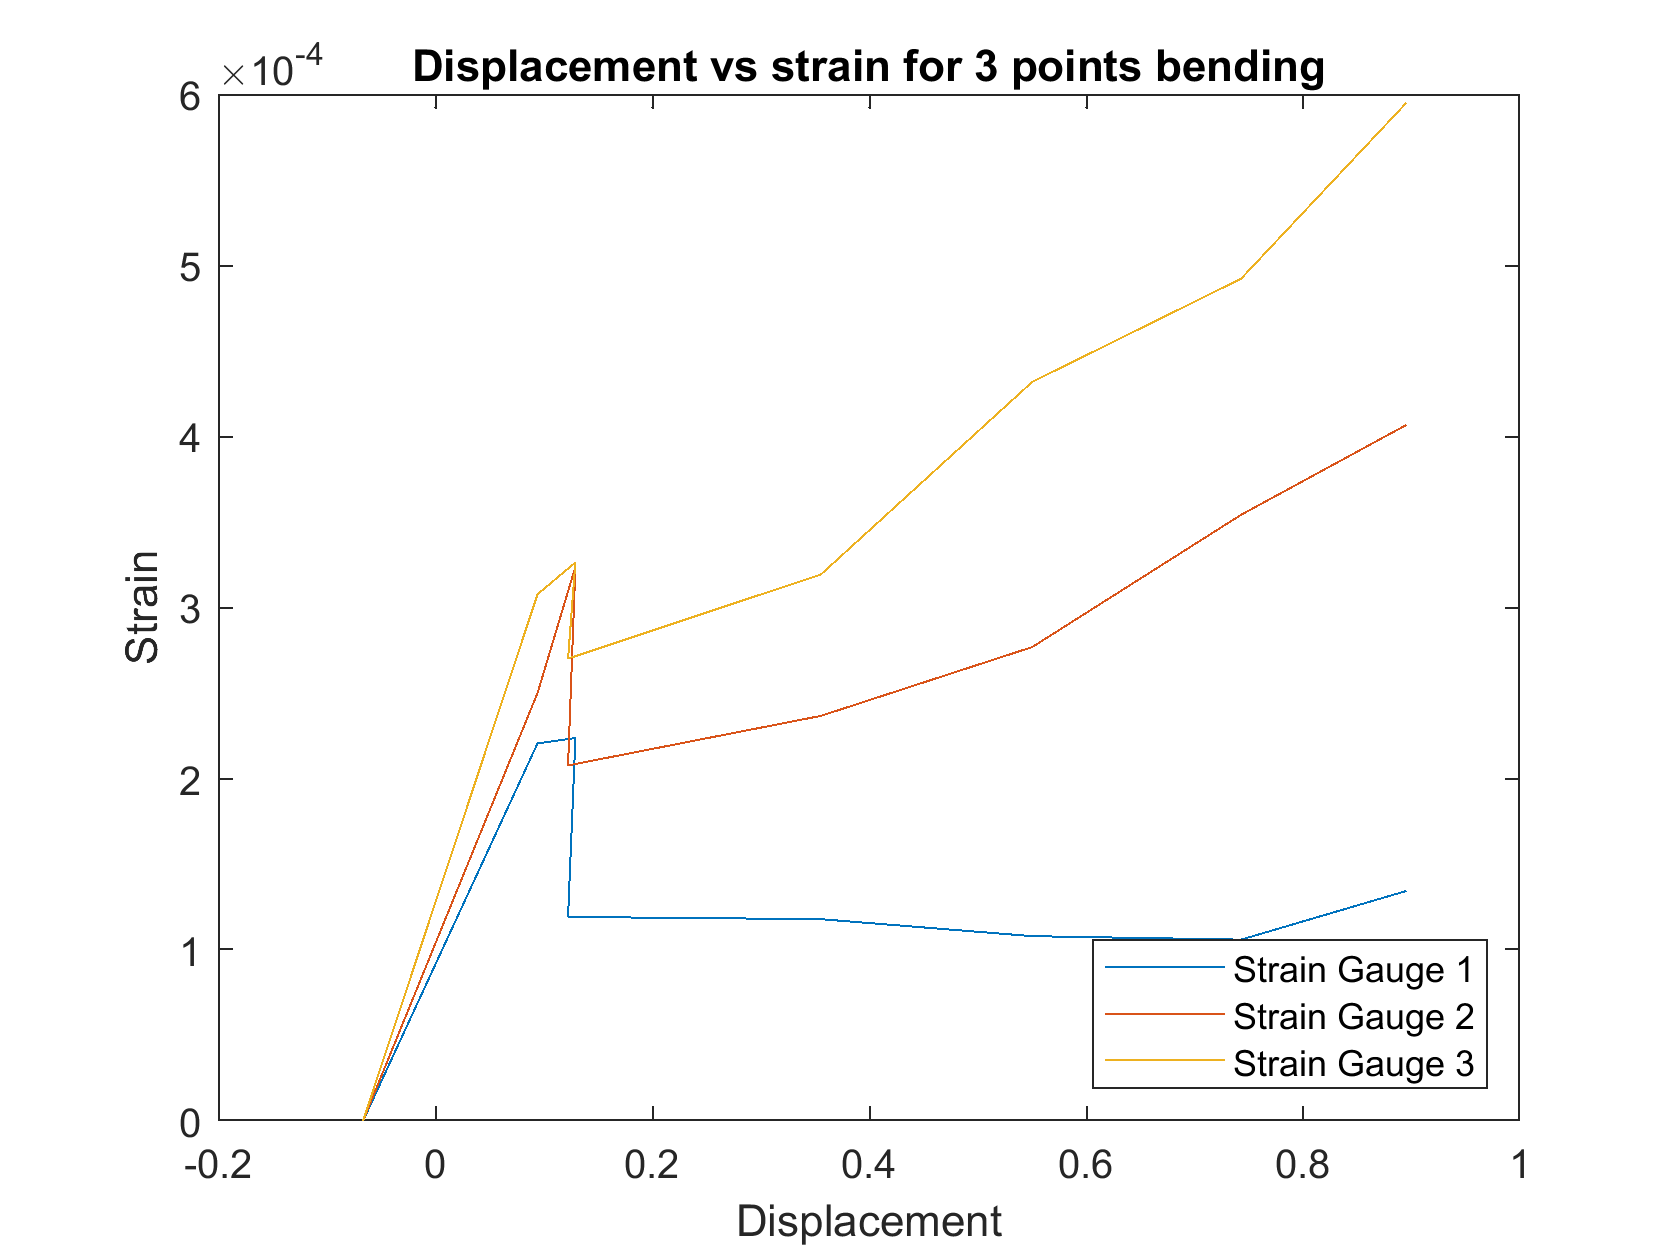

% Strain vs Displacement for 3-point bending from NCORR
displacement = -[0.06635	-0.094508	-0.129403	-0.122613	-0.355676	-0.550519	-0.742947	-0.895336];
SG1 = -[0	-0.000220618	-0.000223732	-0.000119214	-0.0001179182	-0.00010797964	-0.00010595612	-0.0001344236];
SG2 = -[0	-0.0002501	-0.000323736	-0.000207743	-0.00023669	-0.000276908	-0.000354158	-0.000406692];
SG3 = -[0	-0.000307732	-0.000326346	-0.000270148	-0.000319308	-0.000431834	-0.000492094	-0.000594886];
force = -[45.822726	-449.56334	-1466.527103	-3547.833426	-6433.258865	-9514.160002	-12690.38897	-15915.71075];


%draw line of best fit for 3 points bending
coef11 = polyfit(displacement, SG1, 1);
coef21 = polyfit(displacement, SG2, 1);
coef31 = polyfit(displacement, SG3, 1);
dis1 = linspace(0, max(displacement), 10);
yFit1 = polyval(coef11 , dis1);
yFit2 = polyval(coef21 , dis1);
yFit3 = polyval(coef31 , dis1);


% Strain vs Displacement
plot(displacement, SG1)
hold on
plot(displacement, SG2)
plot(displacement, SG3)
% plot(dis1, yFit1, 'k-');
% plot(dis1, yFit2, 'k-');
% plot(dis1, yFit3, 'k-');
legend({'Strain Gauge 1', 'Strain Gauge 2', 'Strain Gauge 3'},'Location','southeast')
xlabel('Displacement')
ylabel('Strain')
title('Displacement vs strain for 3 points bending')
hold off

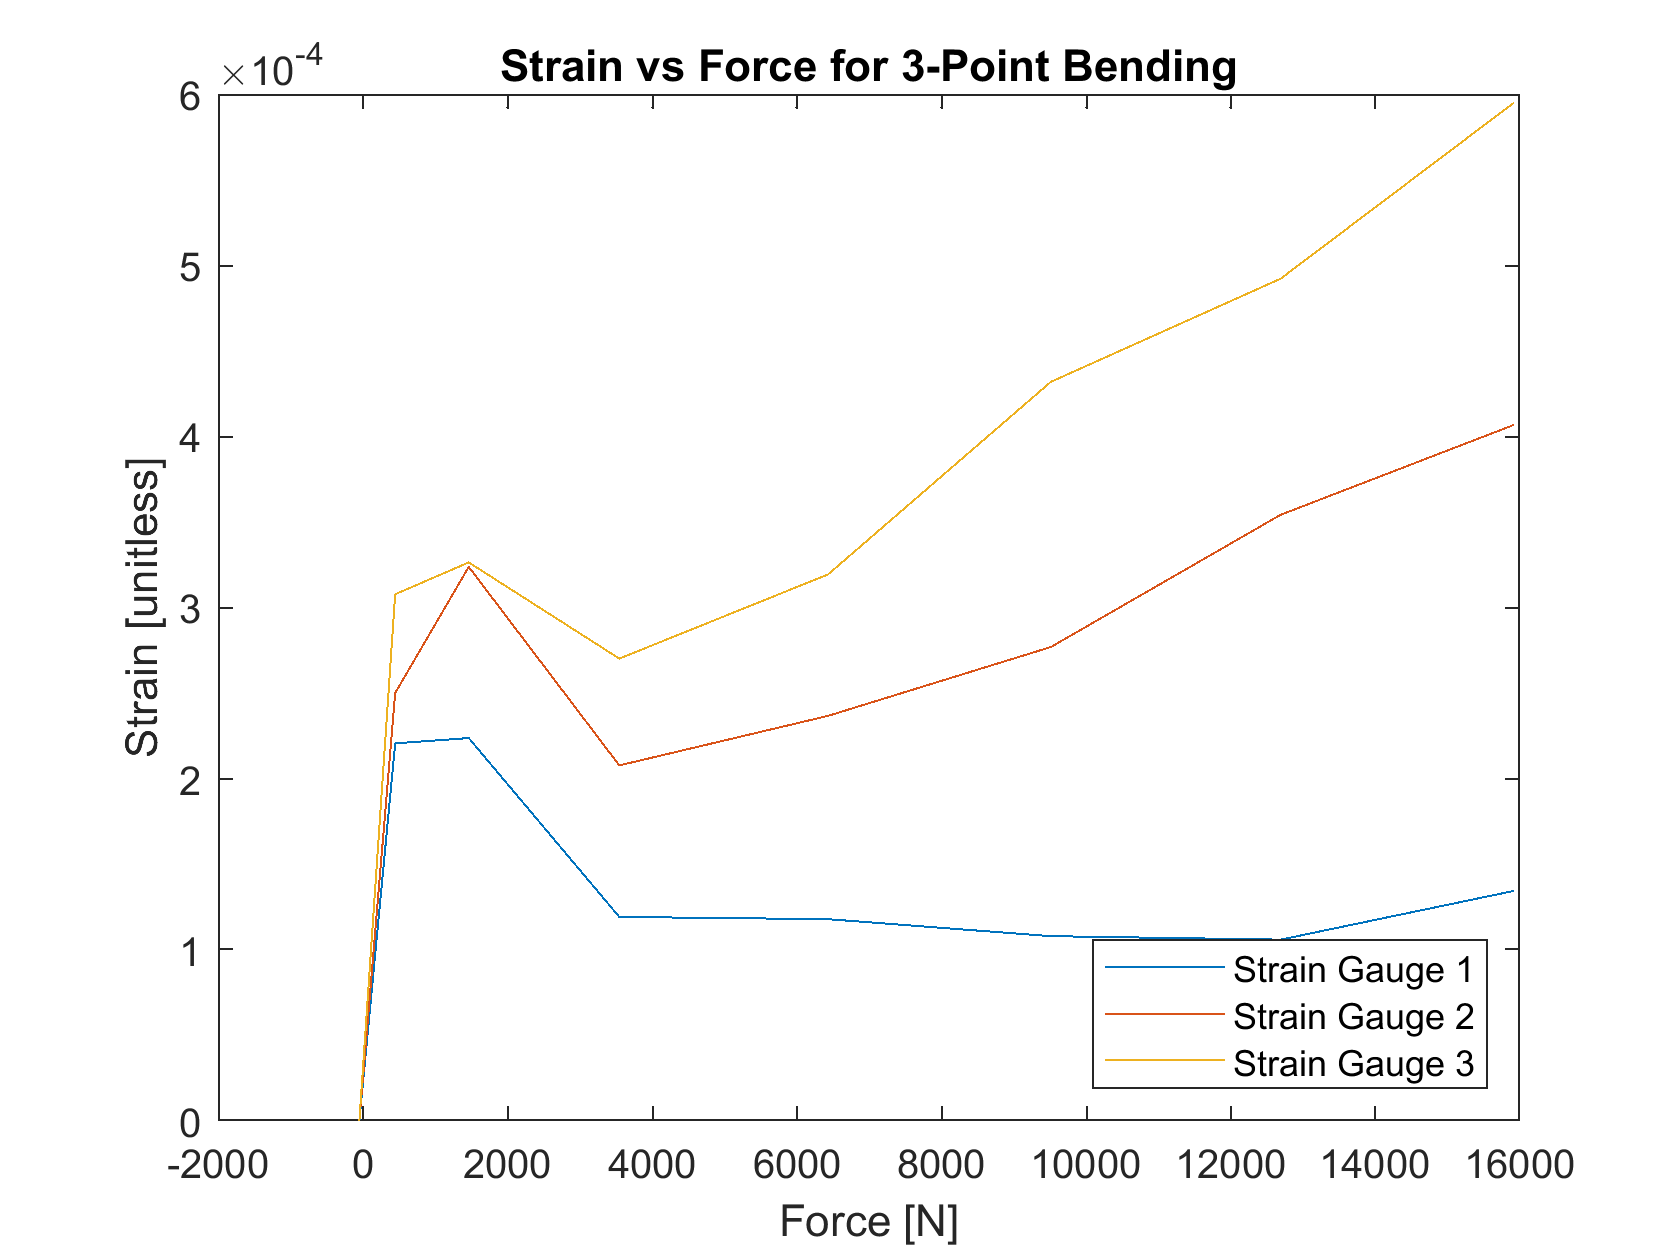



plot(force, SG1)
hold on
plot(force, SG2)
plot(force, SG3)
% plot(dis1, yFit1, 'k-');
% plot(dis1, yFit2, 'k-');
% plot(dis1, yFit3, 'k-');
legend({'Strain Gauge 1', 'Strain Gauge 2', 'Strain Gauge 3'},'Location','southeast')
xlabel('Force [N]')
ylabel('Strain [unitless]')
title('Strain vs Force for 3-Point Bending')
hold off

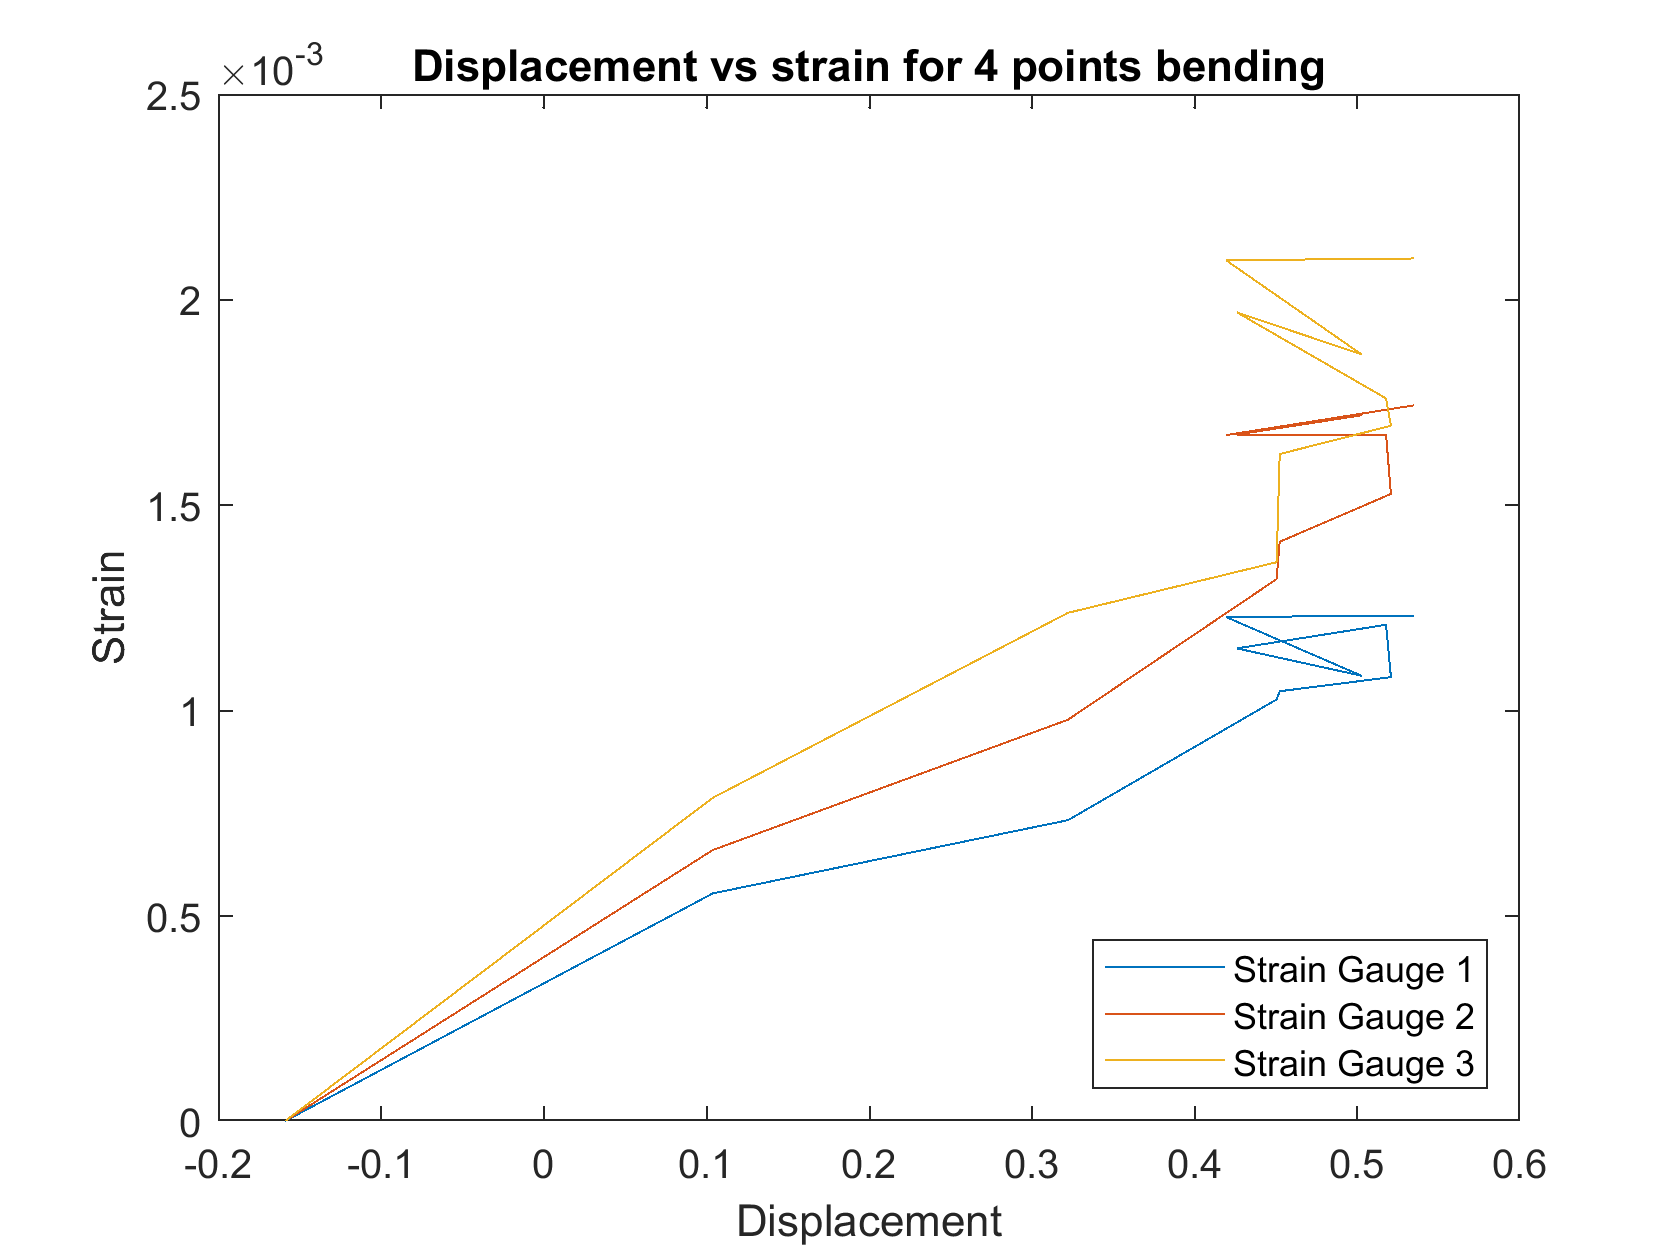

% Strain vs Displacement for 4-point bending from NCORR
displacement = -[0.158717	-0.104026	-0.322249	-0.450453	-0.452343	-0.520697	-0.517687	-0.426023	-0.502742	-0.419373	-0.534977];
SG1 = -[0	-0.000554054	-0.00073228	-0.001026094	-0.001046134	-0.0010805	-0.00120797	-0.001150464	-0.001083736	-0.00122678	-0.00123052];
SG2 = -[0	-0.0006596	-0.00097684	-0.00131908	-0.00140994	-0.00152646	-0.00167052	-0.00167098	-0.00171792	-0.00166962	-0.0017422];
SG3 = -[0	-0.000786818	-0.001237	-0.00136022	-0.00162358	-0.00169236	-0.001759	-0.00196852	-0.00186584	-0.0020953	-0.00209964];
force = -[22.05976	-229.564695	-1114.590972	-2240.011095	-3155.066707	-4618.697248	-6512.786438	-8762.008011	-11999.31326	-15092.02309	-18577.11328];

%draw line of best fit for 3 points bending
coef11 = polyfit(displacement, SG1, 1);
coef21 = polyfit(displacement, SG2, 1);
coef31 = polyfit(displacement, SG3, 1);
dis1 = linspace(0, max(displacement), 10);
yFit1 = polyval(coef11 , dis1);
yFit2 = polyval(coef21 , dis1);
yFit3 = polyval(coef31 , dis1);


plot(displacement, SG1)
hold on
plot(displacement, SG2)
plot(displacement, SG3)
% plot(dis1, yFit1, 'k-');
% plot(dis1, yFit2, 'k-');
% plot(dis1, yFit3, 'k-');
legend({'Strain Gauge 1', 'Strain Gauge 2', 'Strain Gauge 3'},'Location','southeast')
xlabel('Displacement')
ylabel('Strain')
title('Displacement vs strain for 4 points bending')
hold off

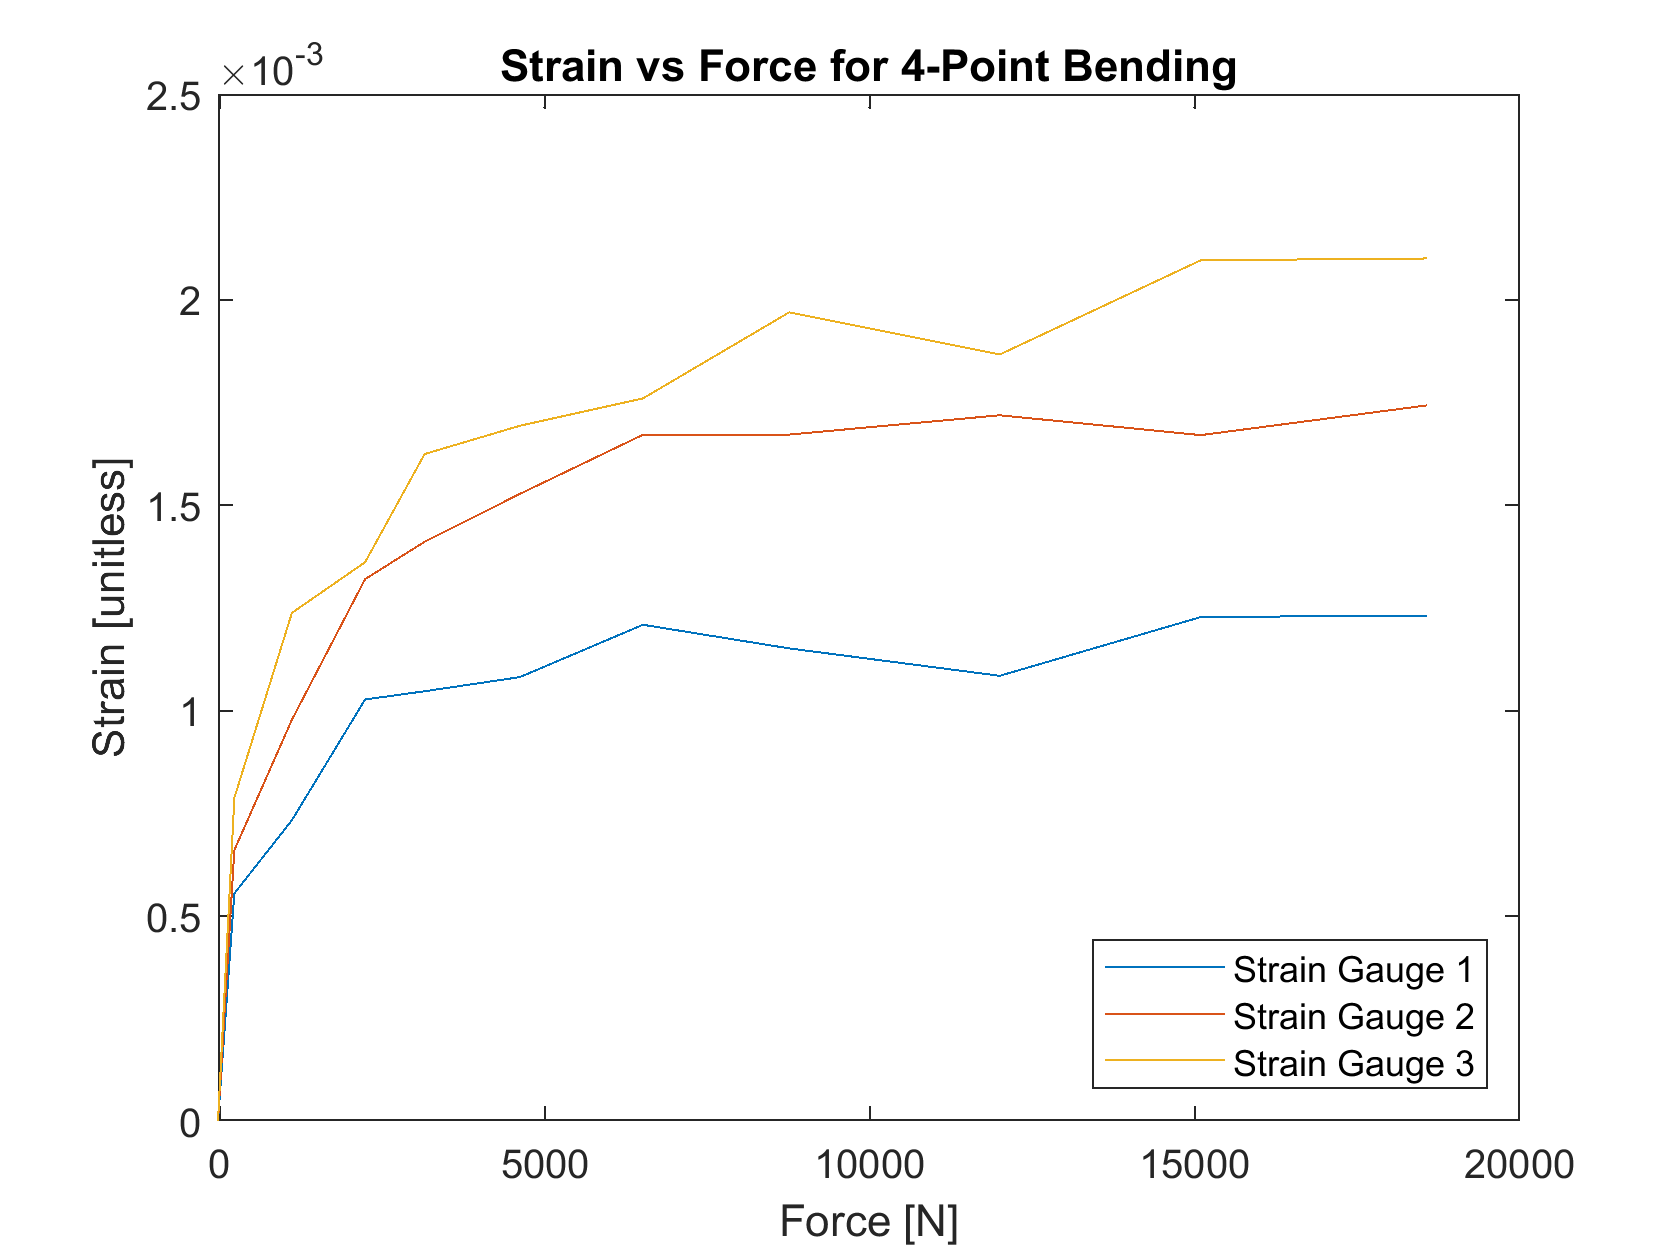



plot(force, SG1)
hold on
plot(force, SG2)
plot(force, SG3)
% plot(dis1, yFit1, 'k-');
% plot(dis1, yFit2, 'k-');
% plot(dis1, yFit3, 'k-');
legend({'Strain Gauge 1', 'Strain Gauge 2', 'Strain Gauge 3'},'Location','southeast')
xlabel('Force [N]')
ylabel('Strain [unitless]')
title('Strain vs Force for 4-Point Bending')
hold off

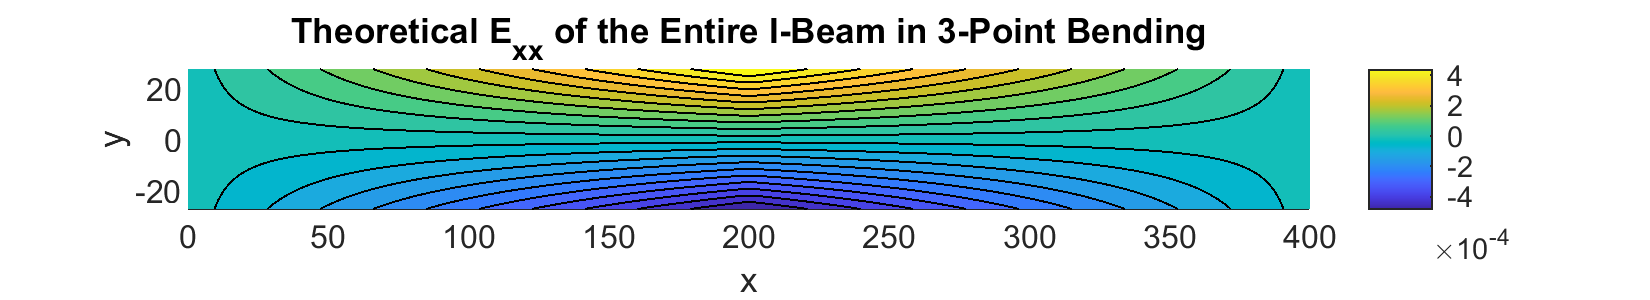

% Theoretical Contour Plots
% 3-point EXX
L = 400; % mm
h = 55; % mm
t = 9.4; % mm
P = 15915.71075; % N
I = 1245500.07; % mm^4
E = 72000; % MPa
G = 26000; % MPa

x = linspace(0,L);
y = linspace(-h/2,h/2);
[X,Y] = meshgrid(x,y);

x2 = linspace(220,250);
y2 = linspace(0,h/2);
[X2,Y2] = meshgrid(x2,y2);

M = (P/2).*X;
M(:, 51:end) = -(P/2).*X(:, 51:end) + (P*L)/2;
SXX = M.*Y./I; % MPa
EXX = SXX./E;

M2 = -(P/2).*X2 + (P*L)/2;
SXX2 = M2.*Y2./I; % MPa
EXX2 = SXX2./E;

V = nan(size(X)); % N
V(:, 1:50) = P/2;
V(:, 51:end) = -P/2;

V2 = nan(size(X2));
V2 = -P/2;

Q = -4.7.*Y.^2 + 75302.46;
Q2 = -4.7.*Y2.^2 + 75302.46;

SXY = (V.*Q)./(I.*t);
EXY = SXY ./ (2*G);

SXY2 = (V2.*Q2)./(I.*t);
EXY2 = SXY2 ./ (2*G);

figure;
hold on;
contourf(X,Y,EXX,20)
xlabel('x')
ylabel('y')
contourcbar
title('Theoretical E_{xx} of the Entire I-Beam in 3-Point Bending')
x0=10;
y0=10;
width=550;
height=100;
set(gcf,'position',[x0,y0,width,height])
hold off;

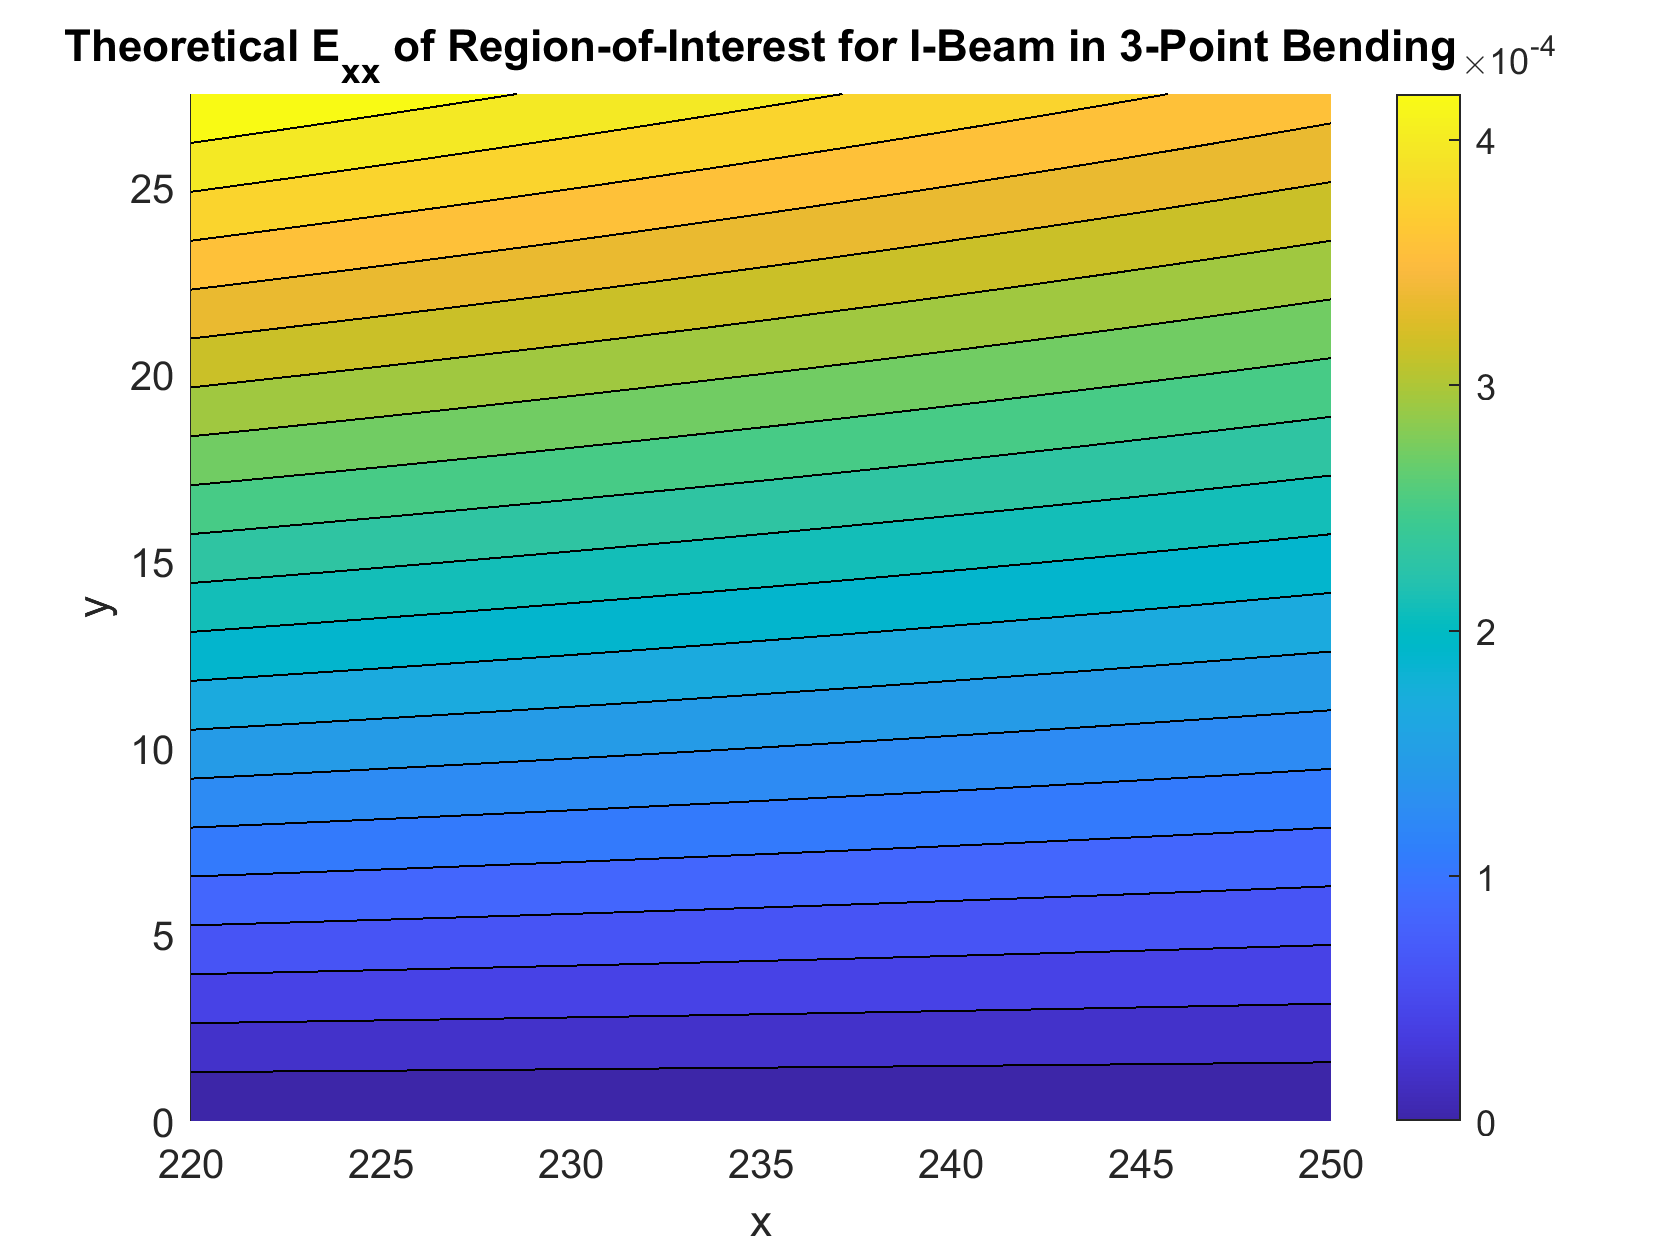


figure;
hold on;
contourf(X2,Y2,EXX2,20)
xlabel('x')
ylabel('y')
contourcbar
title('Theoretical E_{xx} of Region-of-Interest for I-Beam in 3-Point Bending')
hold off;

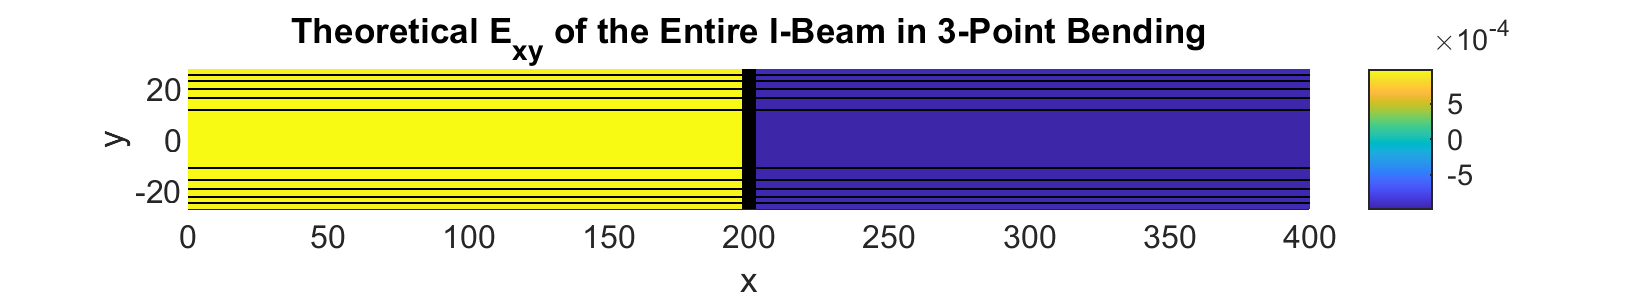


figure;
hold on;
contourf(X,Y,EXY,250)
xlabel('x')
ylabel('y')
contourcbar
title('Theoretical E_{xy} of the Entire I-Beam in 3-Point Bending')
x0=10;
y0=10;
width=550;
height=100;
set(gcf,'position',[x0,y0,width,height])
hold off;

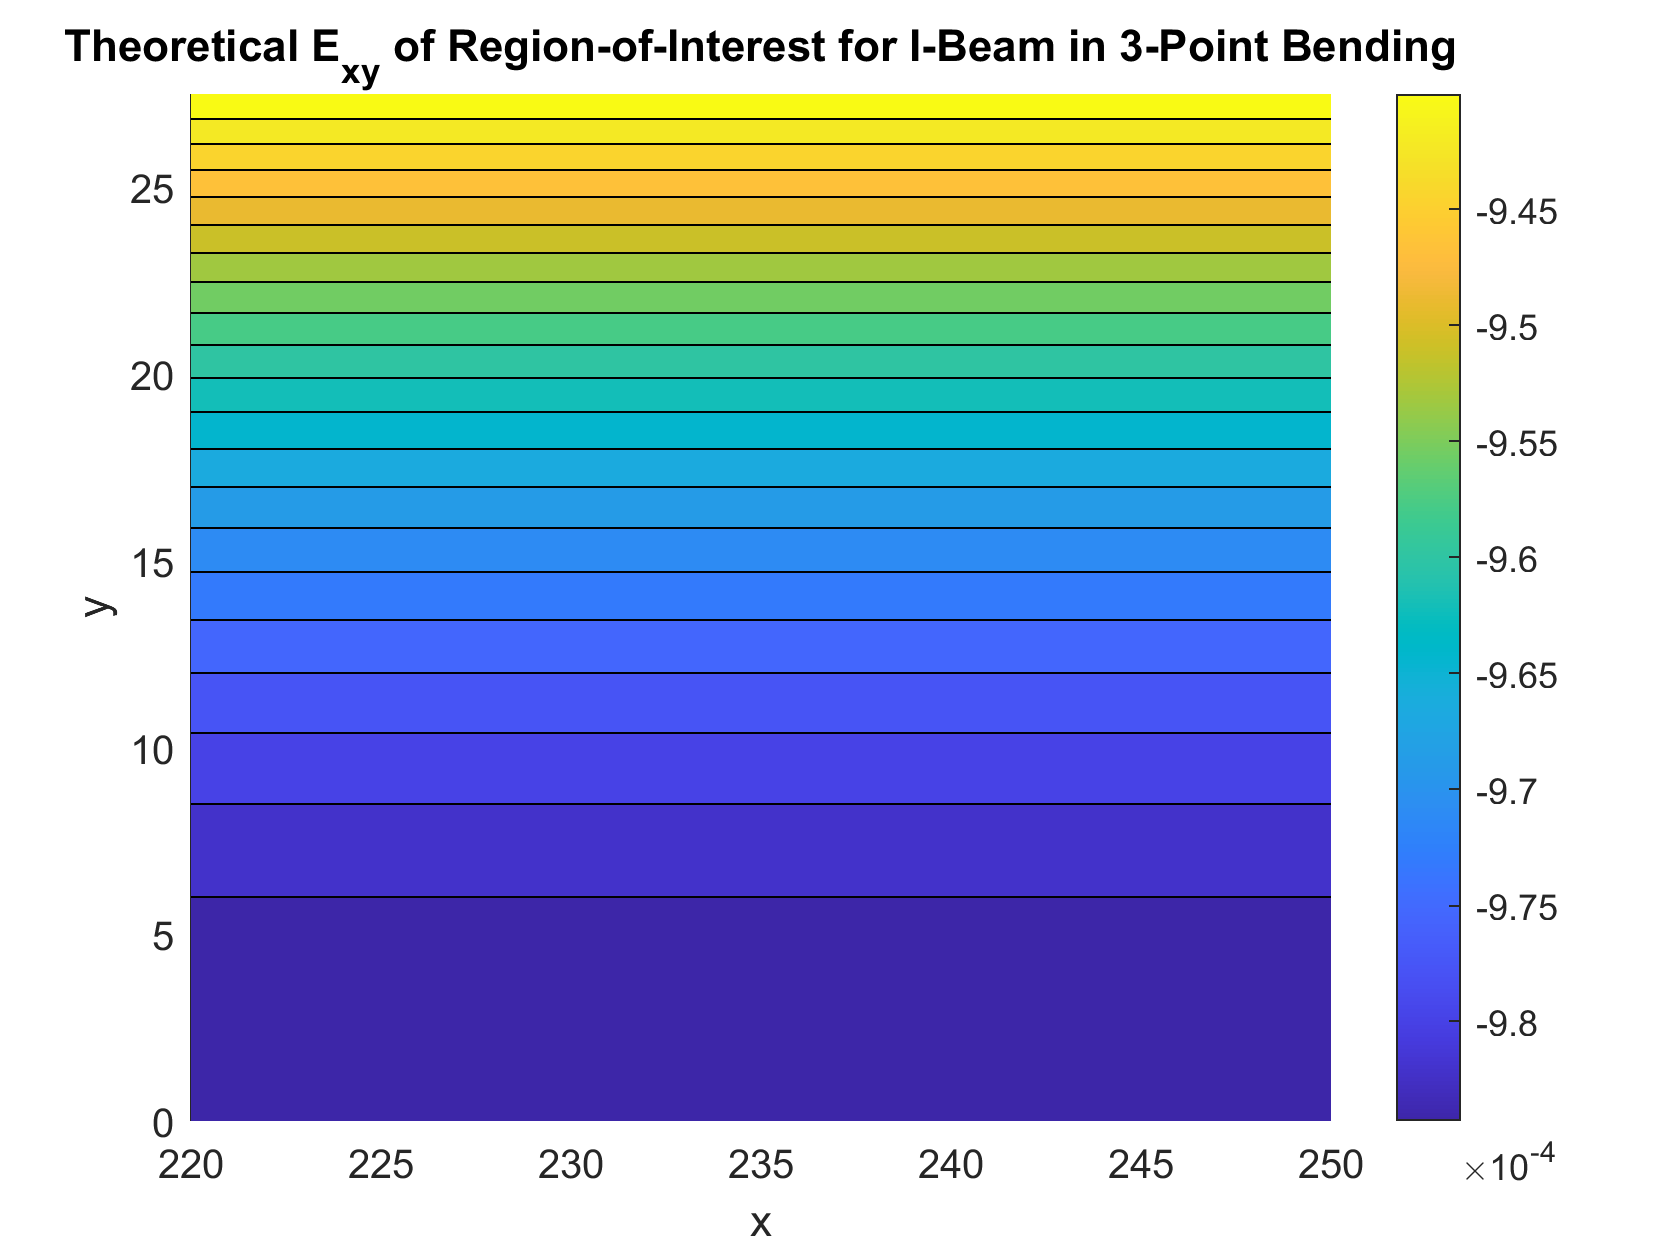


figure;
hold on;
contourf(X2,Y2,EXY2,20)
xlabel('x')
ylabel('y')
contourcbar
title('Theoretical E_{xy} of Region-of-Interest for I-Beam in 3-Point Bending')
hold off;

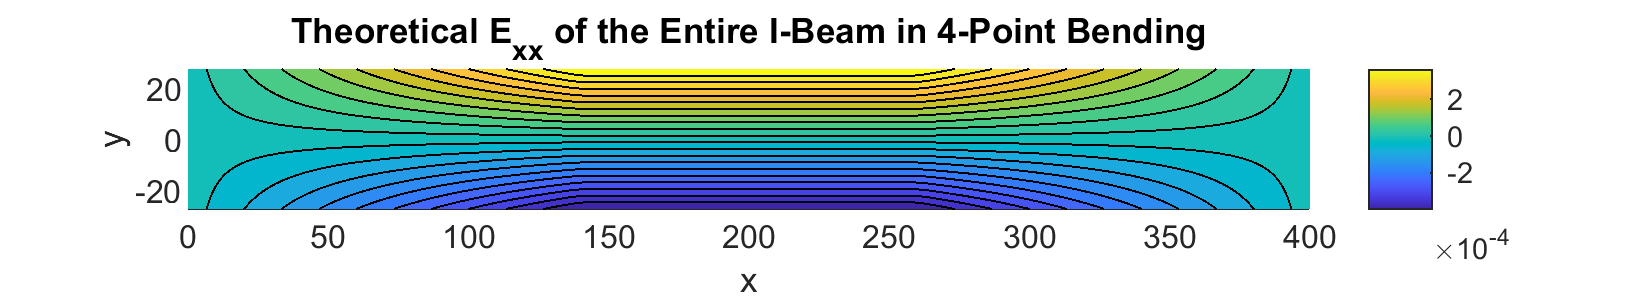

% 4-point bending
L = 400; % mm
L_out = 140; % mm
h = 55; % mm
t = 9.4; % mm
P = 18577.11328; % N (CHANGE)
I = 1245500.07; % mm^4
E = 72000; % MPa
G = 26000; % MPa

x = linspace(0,L);
y = linspace(-h/2,h/2);
[X,Y] = meshgrid(x,y);

x2 = linspace(220,250);
y2 = linspace(0,h/2);
[X2,Y2] = meshgrid(x2,y2);

M = (P/2).*X;
M(:, 36:65) = P*L_out/2;
M(:, 66: end) = -(P/2).*X(:, 66:end) + (P*L)/2;
SXX = M.*Y./I; % MPa
EXX = SXX./E;

M2 = P*L_out/2;
SXX2 = M2.*Y2./I; % MPa
EXX2 = SXX2./E;

V = nan(size(X));
V(:, 1:35) = P/2;
V(:, 36:65) = 0;
V(:, 66:end) = -P/2;

figure;
hold on;
contourf(X,Y,EXX,20)
xlabel('x')
ylabel('y')
contourcbar
title('Theoretical E_{xx} of the Entire I-Beam in 4-Point Bending')
x0=10;
y0=10;
width=550;
height=100;
set(gcf,'position',[x0,y0,width,height])
hold off;

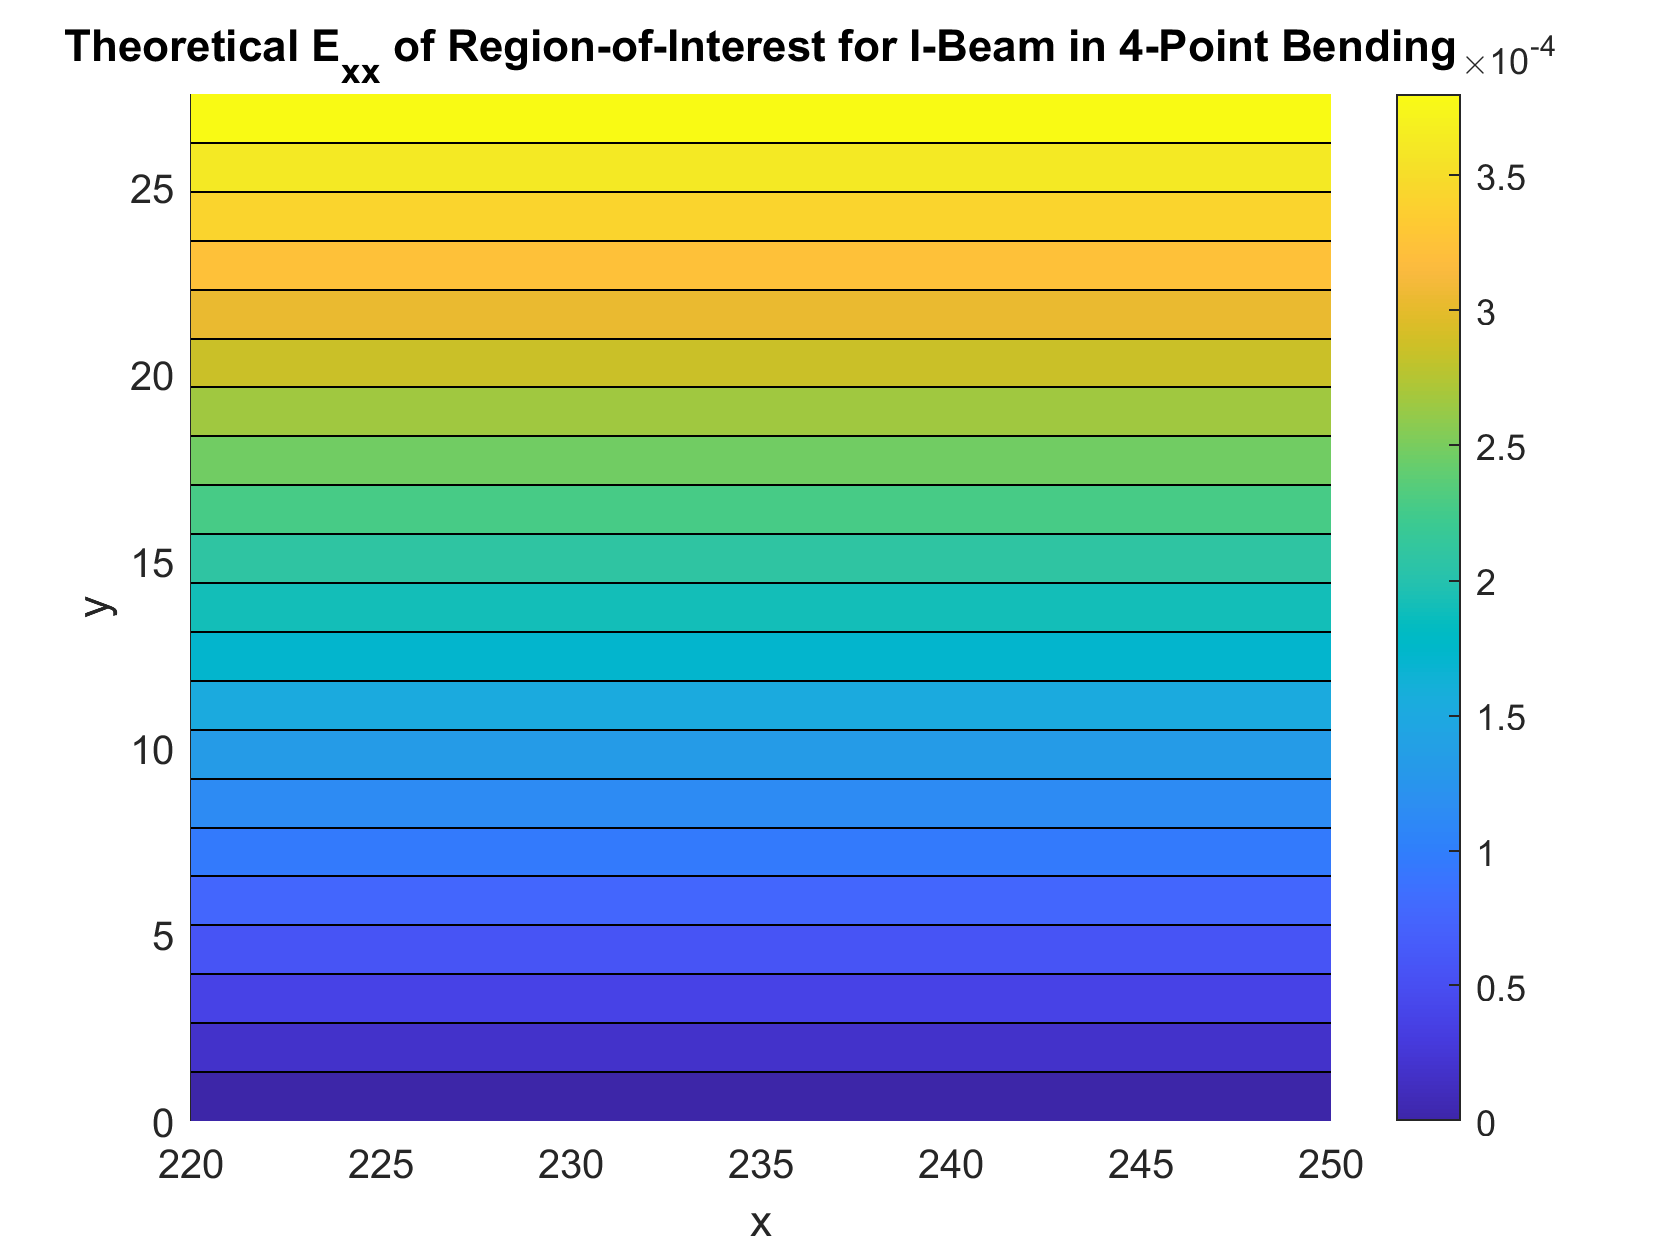


figure;
hold on;
contourf(X2,Y2,EXX2,20)
xlabel('x')
ylabel('y')
contourcbar
title('Theoretical E_{xx} of Region-of-Interest for I-Beam in 4-Point Bending')
hold off;